## Задание 0. Синтез математической модели объекта управления.

function observable(A, C)
    Ob = obsv(A, C)
    rank_Ob = rank(Ob)
    if rank_Ob == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
function controllable(A, B)
    Co = ctrb(A, B)
    rank_Co = rank(Co)
    if rank_Co == size(A, 1)
        fprintf('YES\n');
    else
        fprintf('NO\n');
    end
end
A = [0 1; 0 0];
B = [0; 1];
C = [1 0];
Bw = [1 0; 1 0];
Dw = [0 1];
CZ1 = [10 0; 0 0];
DZ1 = [0; 1];
CZ2 = [10 50; 0 0];
DZ2 = [0; 1];

observable(A, C)

Ob =      1     0
     0     1


rank_Ob = 2

YES


observable(A, CZ1)

Ob =     10     0
     0     0
     0    10
     0     0


rank_Ob = 2

YES


observable(A, CZ2)

Ob =     10    50
     0     0
     0    10
     0     0


rank_Ob = 2

YES


controllable(A, B)

Co =      0     1
     1     0


rank_Co = 2

YES


controllable(A, Bw)

Co =      1     0     1     0
     1     0     0     0


rank_Co = 2

YES


## Задание 1. Синтез H2-регулятора по состоянию.

function [K] = get_K_Ric(A, B, CZ, DZ)
    Q = CZ'*CZ;
    R = DZ'*DZ;
    [~,K,~] = icare(A, B, Q, R, [], [], [], 1);
end
function L = get_L_Ric(A, C, Bw, Dw)
    Q = Bw*Bw';
    R = Dw*Dw';
    [P1,~,~] = icare(A', C', Q, R, [], [], [], 1);    
    L = -P1* C' * inv(R);    
end
function plot_frequency_responses(sys, idx)
    w = logspace(-2, 2, 500); % Частоты от 0.01 до 100 рад/с, 500 точек
    
    % --- Построение покомпонентных АЧХ ---
    figure;
    bodemag(sys, w);
    grid on;
    title('Покомпонентные АЧХ (Bode Plot)');
    exportgraphics(gcf, ['figs/' int2str(idx) '_bodemag.png'], 'Resolution', 500);
    
    % --- Построение графика сингулярных чисел ---
    figure;
    sigma(sys, w);
    grid on;
    title('График сингулярных чисел (Singular Values)');
    exportgraphics(gcf, ['figs/' int2str(idx) '_sigma.png'], 'Resolution', 500);
end

### Первый вариант

notK = get_K_Ric(A, B, CZ1, DZ1);
K = -notK

K =   -10.0000   -4.4721


sys = ss(A+B*K, Bw, CZ1+DZ1*K, zeros(2, 2));
TF = tf(sys)

TF =
 
  From input 1 to output...
          10 s + 54.72
   1:  ------------------
       s^2 + 4.472 s + 10
 
         -14.47 s - 10
   2:  ------------------
       s^2 + 4.472 s + 10
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Properties


norm(sys, 2)

ans = 8.3183

norm(sys, inf)

ans = 6.1117

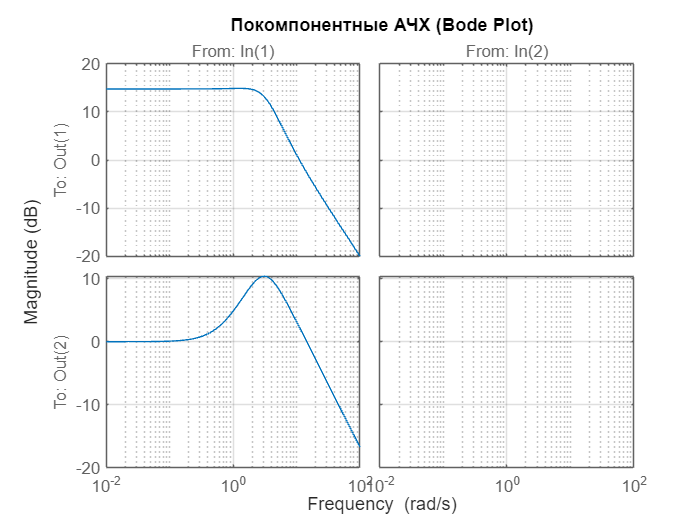

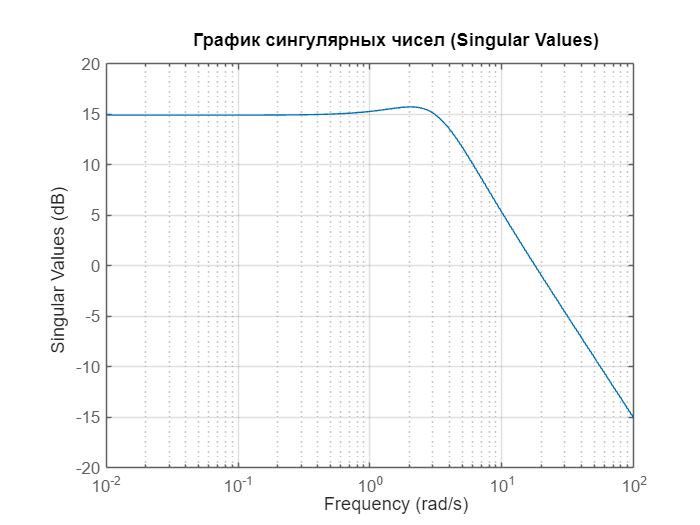

plot_frequency_responses(sys, 1)

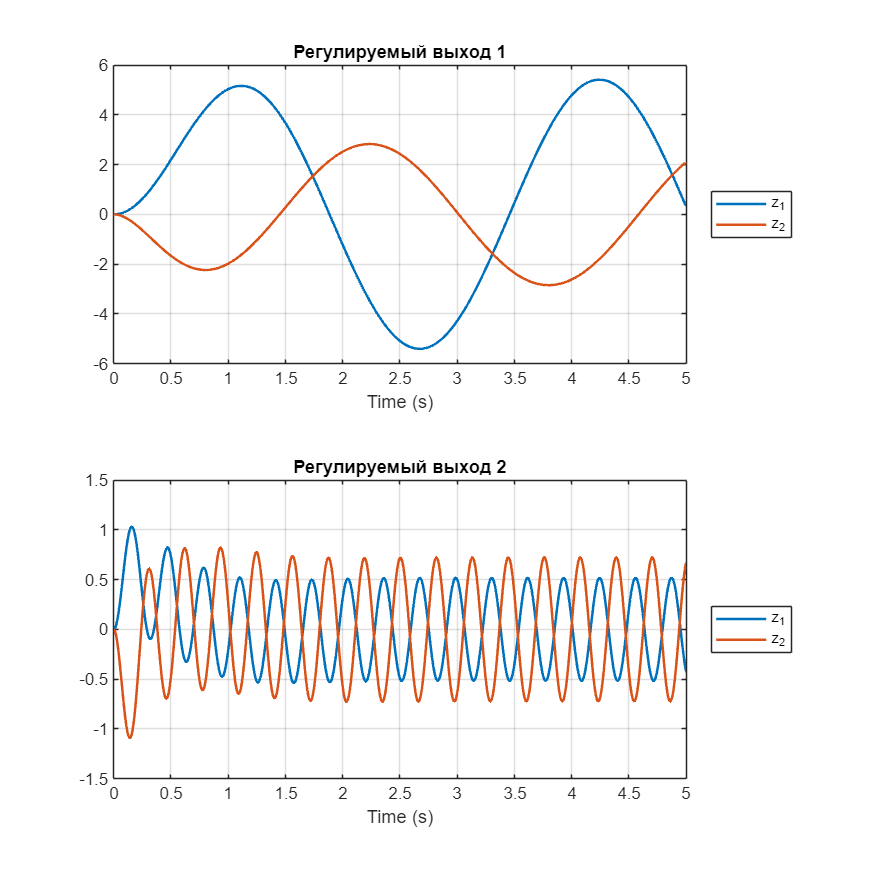

x0 = [0; 0];

model_name = 'task1';
load_system(model_name);

assignin('base', 'CZ', CZ1);
assignin('base', 'DZ', DZ1);
assignin('base', 'w', 2);

sim_out = sim(model_name, 'StopTime', num2str(5));
t1 = sim_out.tout;
z1 = squeeze(sim_out.yout{3}.Values.Data);

assignin('base', 'w', 20);
sim_out = sim(model_name, 'StopTime', num2str(5));
t2 = sim_out.tout;
z2 = squeeze(sim_out.yout{3}.Values.Data);

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t1, z1(1, :), 'LineWidth', 1.5); hold on;
plot(t1, z1(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 1');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t2, z2(1, :), 'LineWidth', 1.5); hold on;
plot(t2, z2(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 2');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/1_sim.png'], 'Resolution', 500);

### Второй вариант

notK = get_K_Ric(A, B, CZ2, DZ2);
K = -notK

K =   -10.0000  -50.1996


sys = ss(A+B*K, Bw, CZ2+DZ2*K, zeros(2, 2));
TF = tf(sys)

TF =
 
  From input 1 to output...
           60 s + 12
   1:  -----------------
       s^2 + 50.2 s + 10
 
         -60.2 s - 10
   2:  -----------------
       s^2 + 50.2 s + 10
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Properties


norm(sys, 2)

ans = 8.4968

norm(sys, inf)

ans = 1.6972

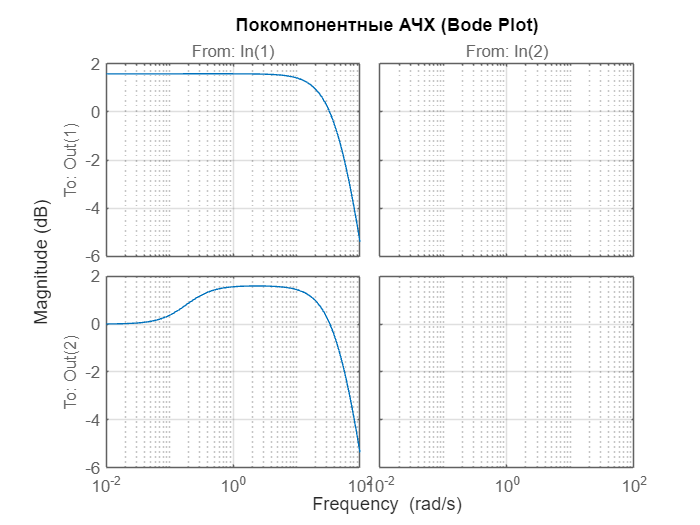

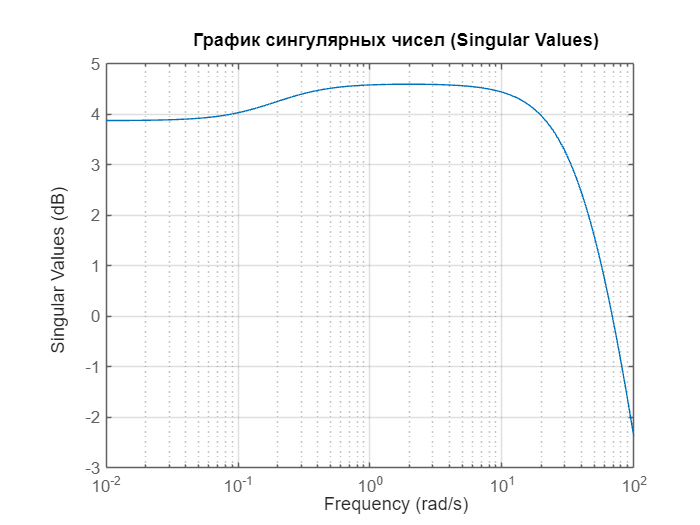

plot_frequency_responses(sys, 2)

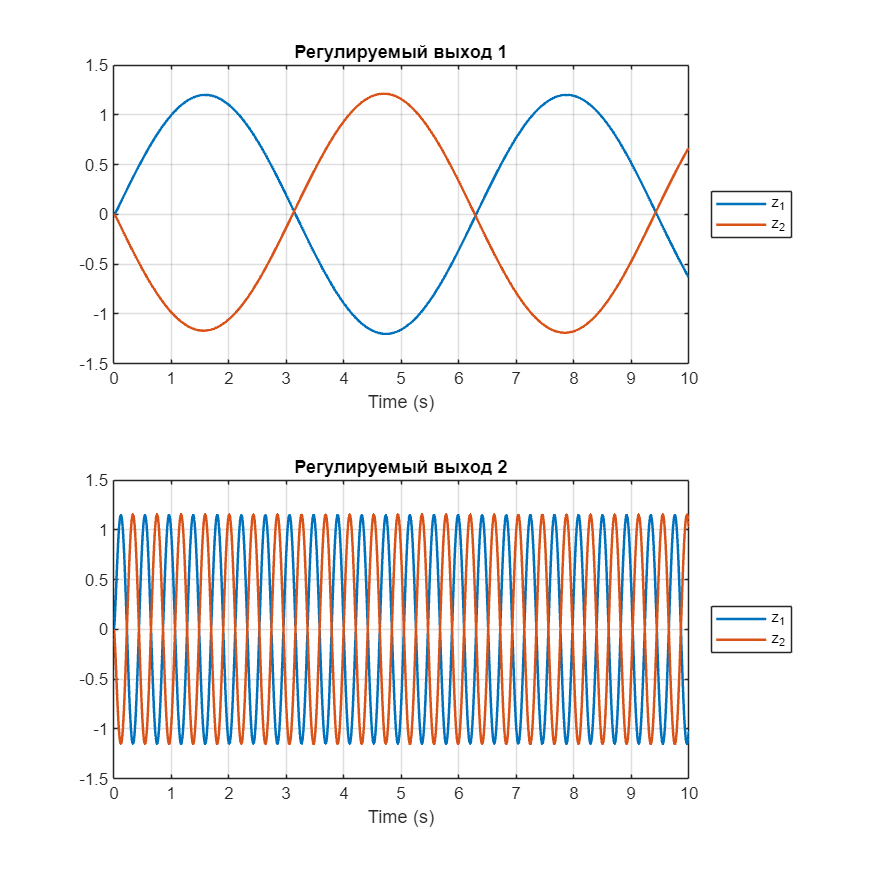

x0 = [0; 0];

model_name = 'task1';
load_system(model_name);

assignin('base', 'CZ', CZ2);
assignin('base', 'DZ', DZ2);
assignin('base', 'w', 1);

sim_out = sim(model_name, 'StopTime', num2str(10));
t1 = sim_out.tout;
z1 = squeeze(sim_out.yout{3}.Values.Data);

assignin('base', 'w', 15);
sim_out = sim(model_name, 'StopTime', num2str(10));
t2 = sim_out.tout;
z2 = squeeze(sim_out.yout{3}.Values.Data);

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t1, z1(1, :), 'LineWidth', 1.5); hold on;
plot(t1, z1(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 1');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t2, z2(1, :), 'LineWidth', 1.5); hold on;
plot(t2, z2(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 2');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/2_sim.png'], 'Resolution', 500);

## Задание 2. Синтез H2-регулятора по выходу.

### Первый вариант

notK = get_K_Ric(A, B, CZ1, DZ1);
K = -notK

K =   -10.0000   -4.4721


L = get_L_Ric(A, C, Bw, Dw)

L =    -1.7321
   -1.0000


sys = ss([A B*K; -L*C A+B*K+L*C], [Bw; -L*Dw], [CZ1 DZ1*K], zeros(2, 2));
TF = tf(sys)

TF =
 
  From input 1 to output...
          10 s^3 + 72.04 s^2 + 249.5 s + 187.5
   1:  ------------------------------------------
       s^4 + 6.204 s^3 + 18.75 s^2 + 21.79 s + 10
 
               -21.79 s^2 - 31.79 s - 10
   2:  ------------------------------------------
       s^4 + 6.204 s^3 + 18.75 s^2 + 21.79 s + 10
 
  From input 2 to output...
                     -217.9 s - 100
   1:  ------------------------------------------
       s^4 + 6.204 s^3 + 18.75 s^2 + 21.79 s + 10
 
       -21.79 s^3 - 10 s^2 - 4.227e-16 s - 1.94e-16
   2:  --------------------------------------------
        s^4 + 6.204 s^3 + 18.75 s^2 + 21.79 s + 10
 
Continuous-time transfer function.


norm(sys, 2)

ans = 18.6140

norm(sys, inf)

ans = 22.4764

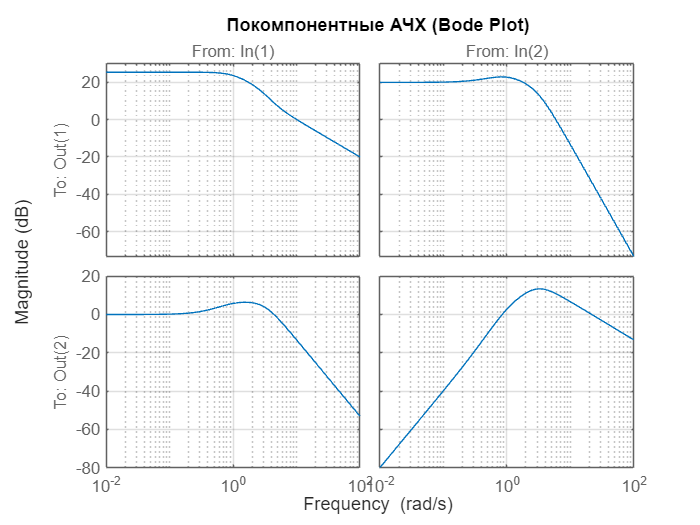

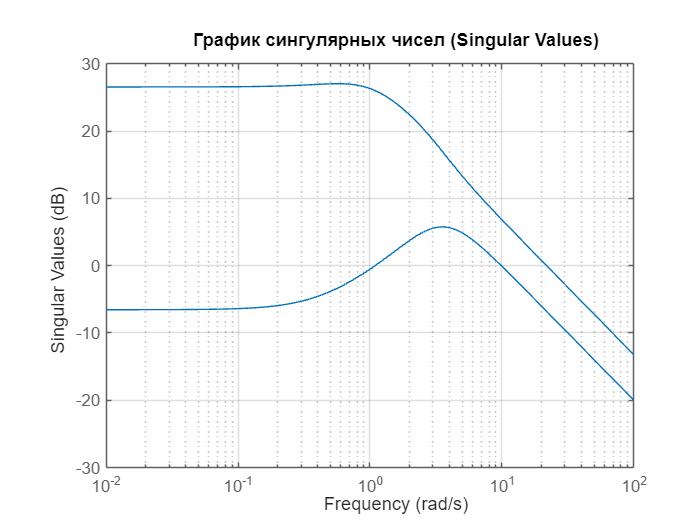

plot_frequency_responses(sys, 3)

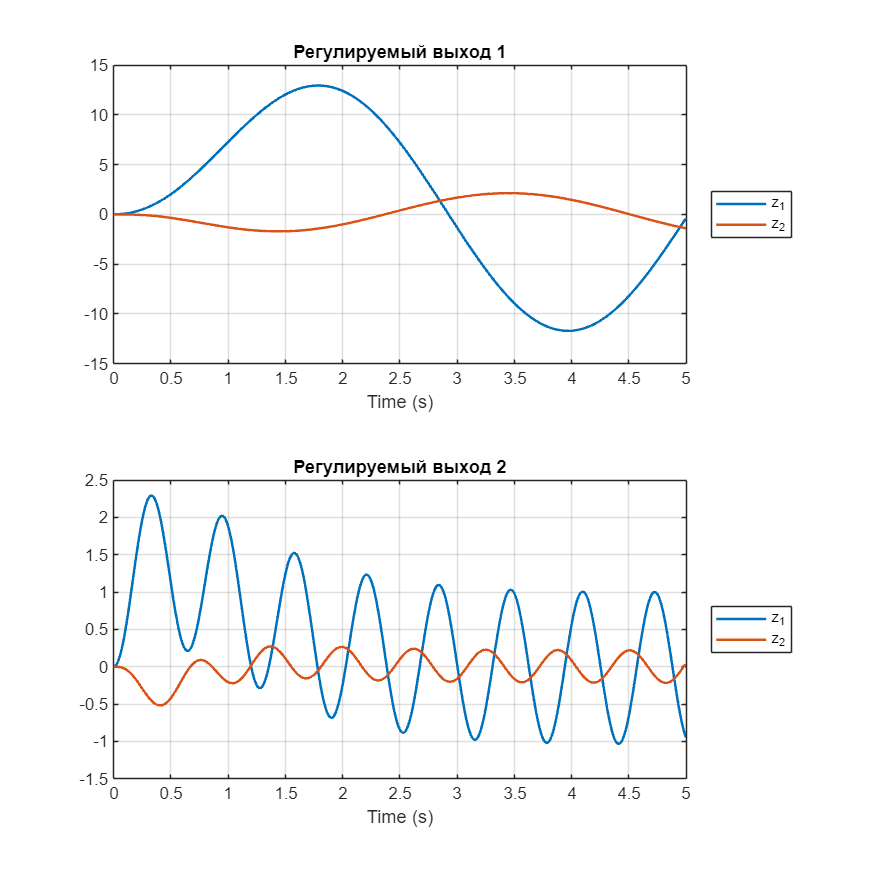

x0 = [0; 0];
x0_hat = [0; 0];

model_name = 'task2';
load_system(model_name);

assignin('base', 'CZ', CZ1);
assignin('base', 'DZ', DZ1);
assignin('base', 'w', 1.5);

sim_out = sim(model_name, 'StopTime', num2str(5));
t1 = sim_out.tout;
z1 = squeeze(sim_out.yout{3}.Values.Data);

assignin('base', 'w', 10);
sim_out = sim(model_name, 'StopTime', num2str(5));
t2 = sim_out.tout;
z2 = squeeze(sim_out.yout{3}.Values.Data);

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t1, z1(1, :), 'LineWidth', 1.5); hold on;
plot(t1, z1(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 1');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t2, z2(1, :), 'LineWidth', 1.5); hold on;
plot(t2, z2(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 2');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/3_sim.png'], 'Resolution', 500);

### Второй вариант

notK = get_K_Ric(A, B, CZ2, DZ2);
K = -notK

K =   -10.0000  -50.1996


L = get_L_Ric(A, C, Bw, Dw)

L =    -1.7321
   -1.0000


sys = ss([A B*K; -L*C A+B*K+L*C], [Bw; -L*Dw], [CZ2 DZ2*K], zeros(2, 2));
TF = tf(sys)

TF =
 
  From input 1 to output...
           60 s^3 + 3126 s^2 + 3020 s + 479.5
   1:  ------------------------------------------
       s^4 + 51.93 s^3 + 97.95 s^2 + 67.52 s + 10
 
               -67.52 s^2 - 77.52 s - 10
   2:  ------------------------------------------
       s^4 + 51.93 s^3 + 97.95 s^2 + 67.52 s + 10
 
  From input 2 to output...
                -3376 s^2 - 1175 s - 100
   1:  ------------------------------------------
       s^4 + 51.93 s^3 + 97.95 s^2 + 67.52 s + 10
 
       -67.52 s^3 - 10 s^2 - 3.245e-15 s - 4.805e-16
   2:  ---------------------------------------------
        s^4 + 51.93 s^3 + 97.95 s^2 + 67.52 s + 10
 
Continuous-time transfer function.


norm(sys, 2)

ans = 55.6252

norm(sys, inf)

ans = 61.4190

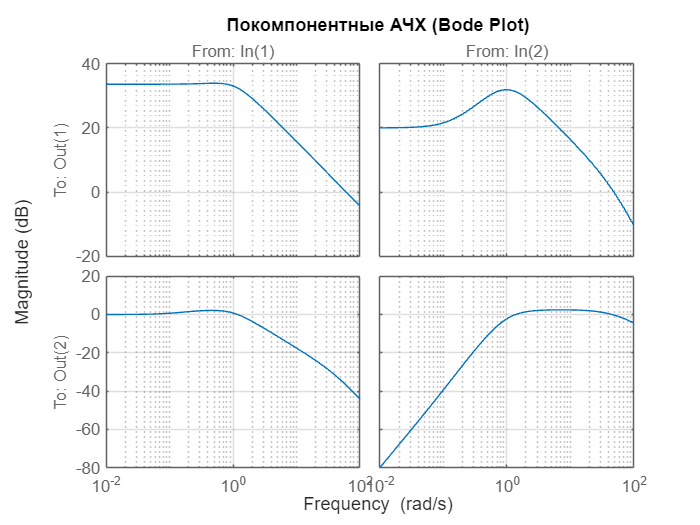

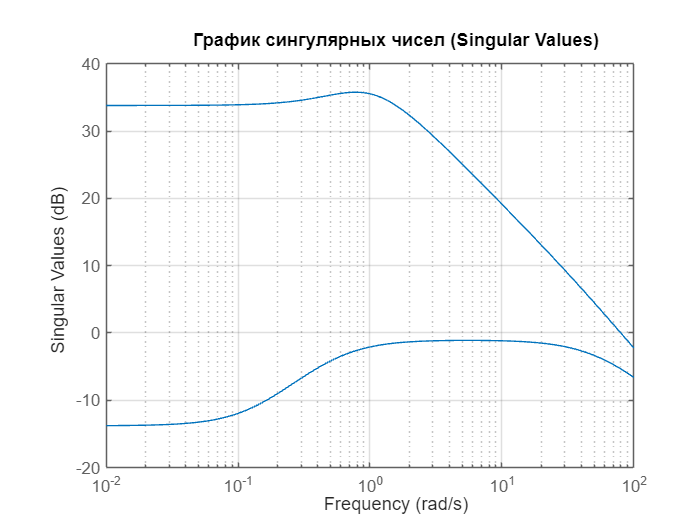

plot_frequency_responses(sys, 4)

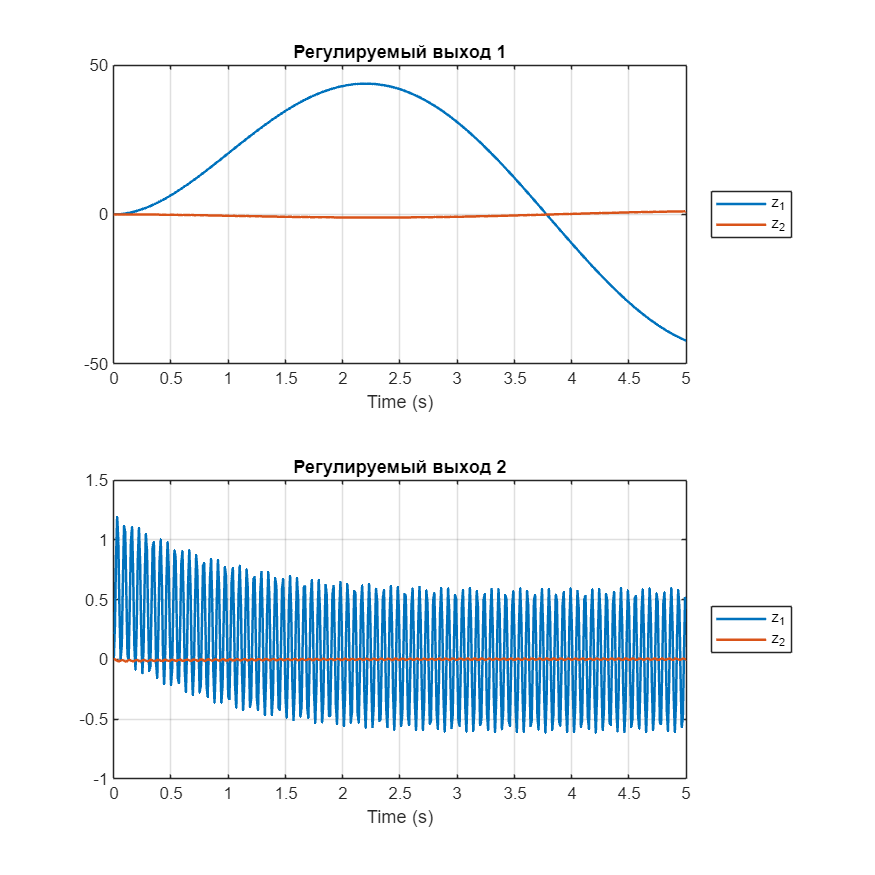

x0 = [0; 0];
x0_hat = [0; 0];

model_name = 'task2';
load_system(model_name);

assignin('base', 'CZ', CZ2);
assignin('base', 'DZ', DZ2);
assignin('base', 'w', 1);

sim_out = sim(model_name, 'StopTime', num2str(5));
t1 = sim_out.tout;
z1 = squeeze(sim_out.yout{3}.Values.Data);

assignin('base', 'w', 100);
sim_out = sim(model_name, 'StopTime', num2str(5));
t2 = sim_out.tout;
z2 = squeeze(sim_out.yout{3}.Values.Data);

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t1, z1(1, :), 'LineWidth', 1.5); hold on;
plot(t1, z1(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 1');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t2, z2(1, :), 'LineWidth', 1.5); hold on;
plot(t2, z2(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 2');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/4_sim.png'], 'Resolution', 500);

## Задание 3. Синтез H∞-регулятора по состоянию.

function [X, K] = get_K_Ric2(A, B, CZ, DZ, Bw, g)
    Q = CZ'*CZ;
    R = DZ'*DZ;
    G = g^(-2)*Bw*Bw';
    [X,~,~] = icare(A, B, Q, R, [], [], G);
    if isempty(X)
        error('Решение уравнения Риккати не найдено.');
    end
    K = -inv(R)*B'*X;
end
CZ = CZ1;
DZ = DZ1;

### Первая гамма

gamma = 3.8;
K = get_K_Ric2(A, B, CZ, DZ, Bw, gamma)

K =  -505.8604 -184.4152


sys = ss(A+B*K, Bw, CZ+DZ*K, zeros(2, 2));
TF = tf(sys)

TF =
 
  From input 1 to output...
            10 s + 1854
   1:  ---------------------
       s^2 + 184.4 s + 505.9
 
         -690.3 s - 505.9
   2:  ---------------------
       s^2 + 184.4 s + 505.9
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Properties


norm(sys, 2)

ans = 36.2207

norm(sys, inf)

ans = 3.7996

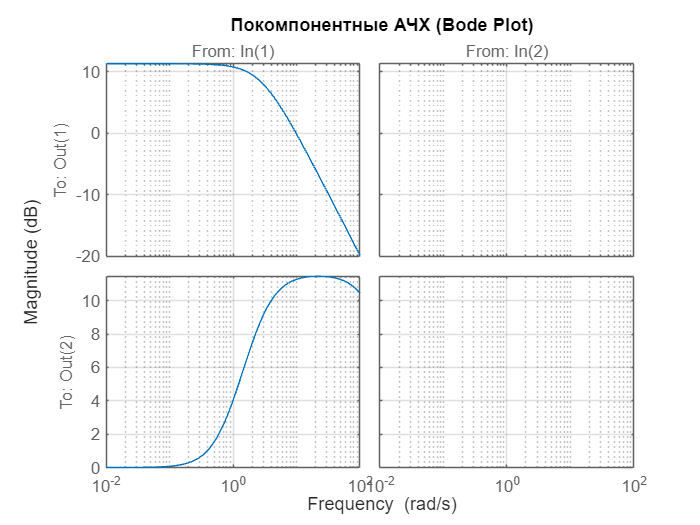

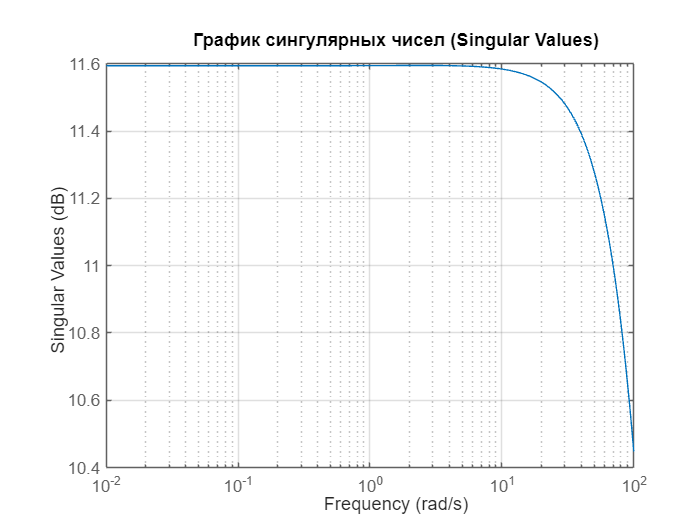

plot_frequency_responses(sys, 5)

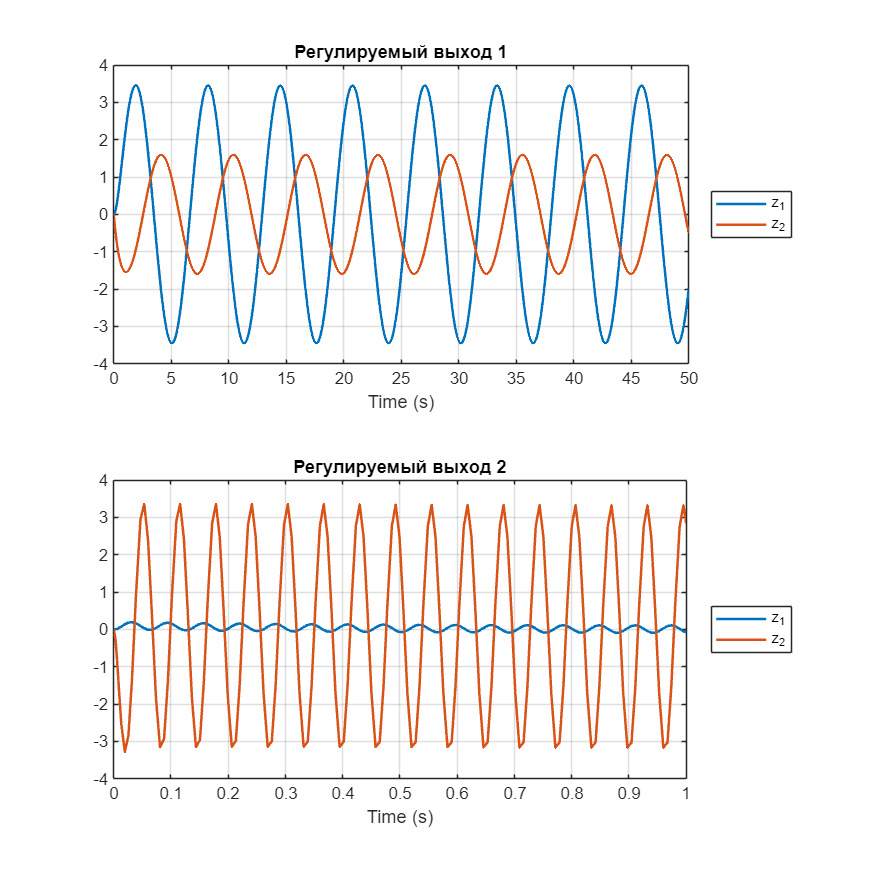

x0 = [0; 0];

model_name = 'task1';
load_system(model_name);

assignin('base', 'CZ', CZ);
assignin('base', 'DZ', DZ);
assignin('base', 'w', 1);

sim_out = sim(model_name, 'StopTime', num2str(50));
t1 = sim_out.tout;
z1 = squeeze(sim_out.yout{3}.Values.Data);

assignin('base', 'w', 100);
sim_out = sim(model_name, 'StopTime', num2str(1));
t2 = sim_out.tout;
z2 = squeeze(sim_out.yout{3}.Values.Data);

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t1, z1(1, :), 'LineWidth', 1.5); hold on;
plot(t1, z1(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 1');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t2, z2(1, :), 'LineWidth', 1.5); hold on;
plot(t2, z2(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 2');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/5_sim.png'], 'Resolution', 500);

### Вторая гамма

gamma = 500;
[~, K] = get_K_Ric2(A, B, CZ, DZ, Bw, gamma)

K =   -10.0006   -4.4724


sys = ss(A+B*K, Bw, CZ+DZ*K, zeros(2, 2));
TF = tf(sys)

TF =
 
  From input 1 to output...
          10 s + 54.72
   1:  ------------------
       s^2 + 4.472 s + 10
 
         -14.47 s - 10
   2:  ------------------
       s^2 + 4.472 s + 10
 
  From input 2 to output...
   1:  0
 
   2:  0
 
Continuous-time transfer function.
Model Properties


norm(sys, 2)

ans = 8.3183

norm(sys, inf)

ans = 6.1115

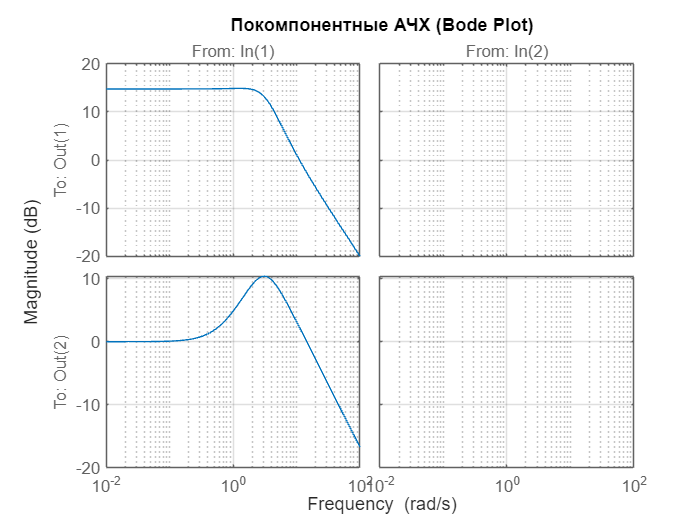

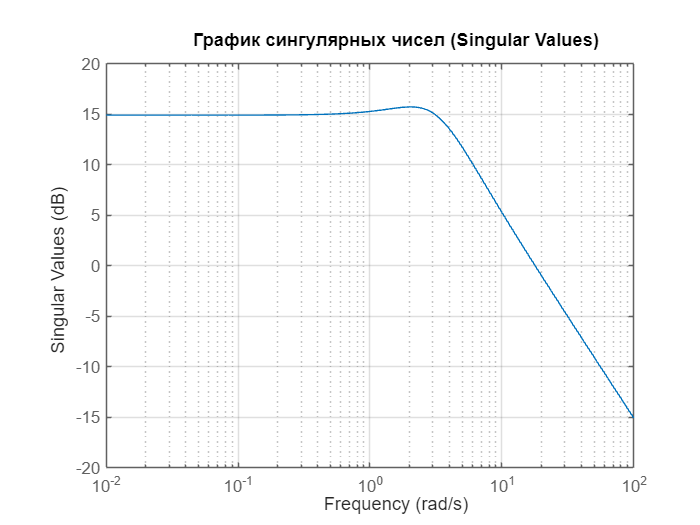

plot_frequency_responses(sys, 6)

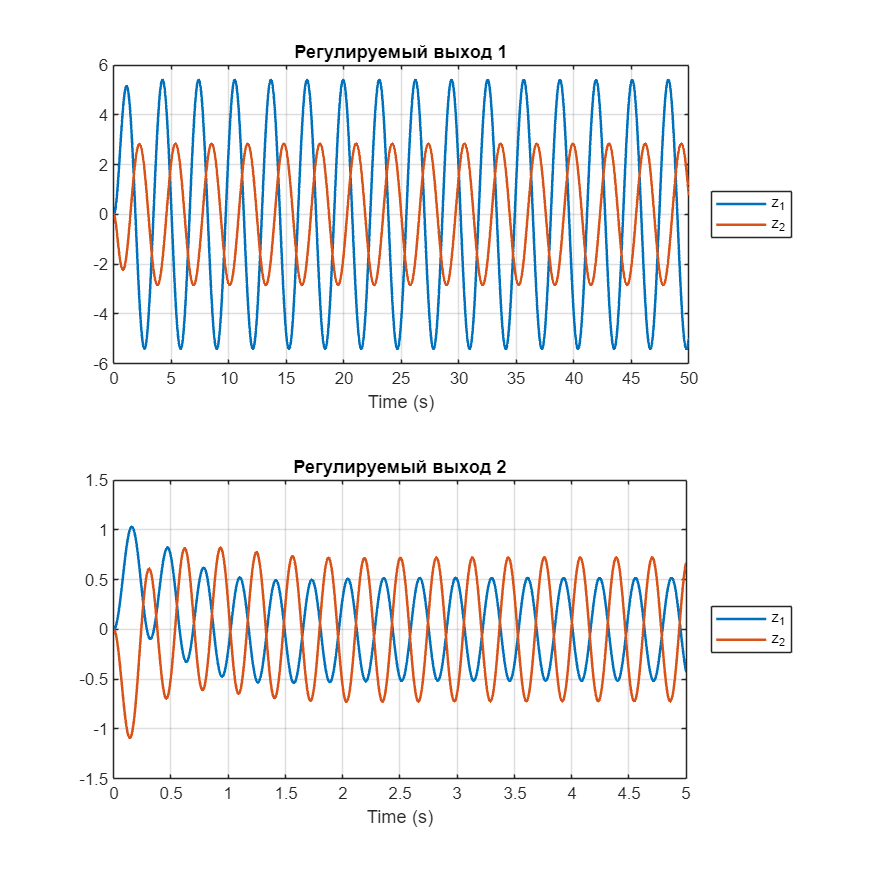

x0 = [0; 0];

model_name = 'task1';
load_system(model_name);

assignin('base', 'CZ', CZ);
assignin('base', 'DZ', DZ);
assignin('base', 'w', 2);

sim_out = sim(model_name, 'StopTime', num2str(50));
t1 = sim_out.tout;
z1 = squeeze(sim_out.yout{3}.Values.Data);

assignin('base', 'w', 20);
sim_out = sim(model_name, 'StopTime', num2str(5));
t2 = sim_out.tout;
z2 = squeeze(sim_out.yout{3}.Values.Data);

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t1, z1(1, :), 'LineWidth', 1.5); hold on;
plot(t1, z1(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 1');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t2, z2(1, :), 'LineWidth', 1.5); hold on;
plot(t2, z2(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 2');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/6_sim.png'], 'Resolution', 500);

## Задание 4. Синтез H∞-регулятора по выходу.

function [K, L] = get_L_Ric2(A, B, C, CZ, DZ, Bw, Dw, g)
    [X, K] = get_K_Ric2(A, B, CZ, DZ, Bw, g);
    Q = Bw*Bw';
    R = Dw*Dw';
    G = g^(-2)*(CZ')*CZ;
    [P,~,~] = icare(A', C', Q, R, [], [], G);
    if isempty(X)
        error('Решение уравнения Риккати не найдено.');
    end
    if max(eig(P*X)) <= g^2
        %error('Условие согласованности не выполнено.');
    end
    L = -P*(eye(2)-g^(-2)*X*P)^(-1)*((C+g^(-1)*Dw*Bw'*X)')*(R)^(-1);
end
CZ = CZ1;
DZ = DZ1;

### Первая гамма

gamma = 14;
[K, L] = get_L_Ric2(A, B, C, CZ, DZ, Bw, Dw, gamma)

K =   -10.8240   -4.7845


L =   -19.2256
  -10.0980


sys = ss([A B*K; -L*C A+B*K+L*C], [Bw; -L*Dw], [CZ DZ*K], zeros(2, 2));
TF = tf(sys)

TF =
 
  From input 1 to output...
            10 s^3 + 250.1 s^2 + 1369 s + 1129
   1:  ---------------------------------------------
       s^4 + 24.01 s^3 + 112.9 s^2 + 256.4 s + 109.3
 
               -256.4 s^2 - 365.7 s - 109.3
   2:  ---------------------------------------------
       s^4 + 24.01 s^3 + 112.9 s^2 + 256.4 s + 109.3
 
  From input 2 to output...
                      -2564 s - 1093
   1:  ---------------------------------------------
       s^4 + 24.01 s^3 + 112.9 s^2 + 256.4 s + 109.3
 
       -256.4 s^3 - 109.3 s^2 - 9.679e-14 s - 4.126e-14
   2:  ------------------------------------------------
        s^4 + 24.01 s^3 + 112.9 s^2 + 256.4 s + 109.3
 
Continuous-time transfer function.


norm(sys, 2)

ans = 42.1182

norm(sys, inf)

ans = 14.3952

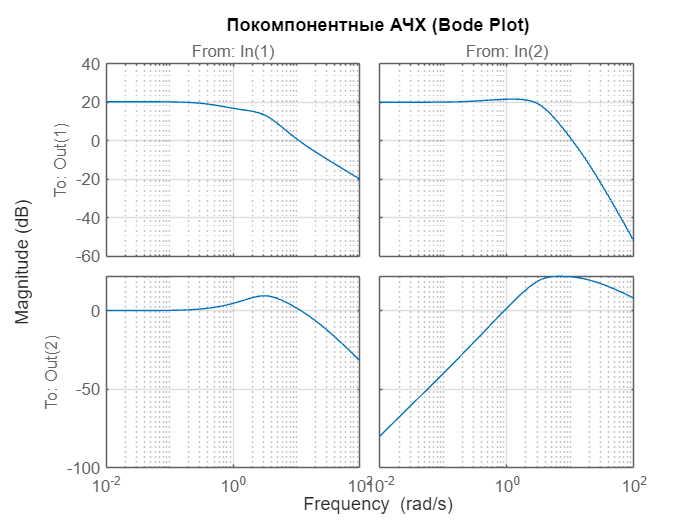

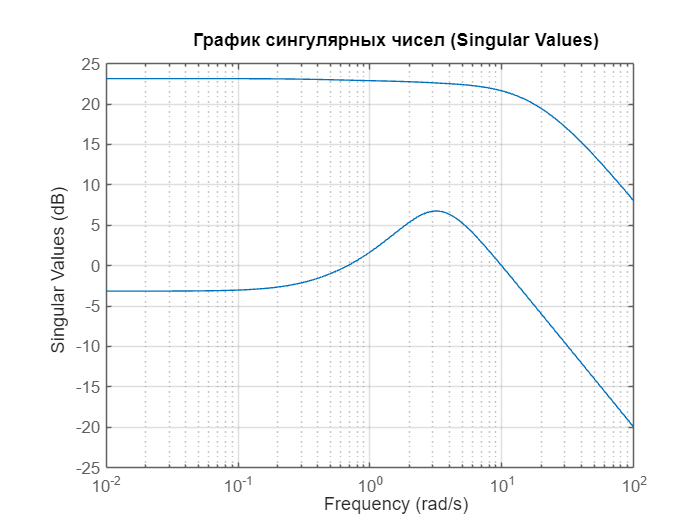

plot_frequency_responses(sys, 7)

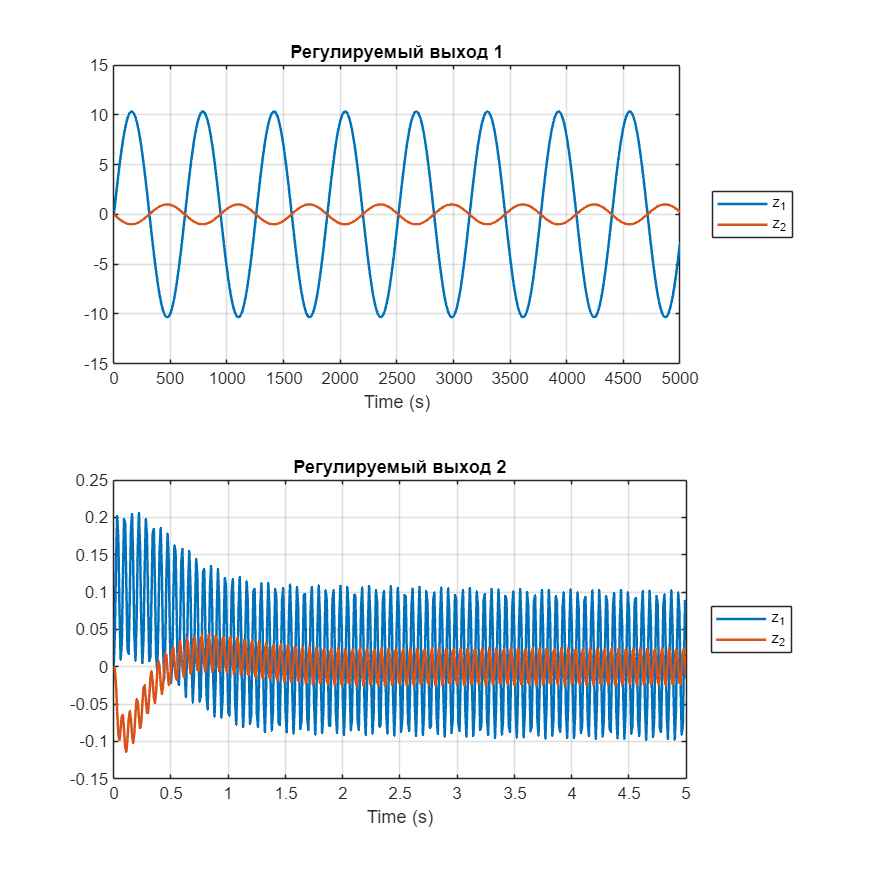

x0 = [0; 0];
x0_hat = [0; 0];

model_name = 'task2';
load_system(model_name);

assignin('base', 'CZ', CZ);
assignin('base', 'DZ', DZ);
assignin('base', 'w', 0.01);

sim_out = sim(model_name, 'StopTime', num2str(5000));
t1 = sim_out.tout;
z1 = squeeze(sim_out.yout{3}.Values.Data);

assignin('base', 'w', 100);
sim_out = sim(model_name, 'StopTime', num2str(5));
t2 = sim_out.tout;
z2 = squeeze(sim_out.yout{3}.Values.Data);

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t1, z1(1, :), 'LineWidth', 1.5); hold on;
plot(t1, z1(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 1');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t2, z2(1, :), 'LineWidth', 1.5); hold on;
plot(t2, z2(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 2');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/7_sim.png'], 'Resolution', 500);

### Гамма побольше

gamma = 1000;
[K, L] = get_L_Ric2(A, B, C, CZ, DZ, Bw, Dw, gamma)

K =   -10.0001   -4.4722


L =    -1.7323
   -1.0002


sys = ss([A B*K; -L*C A+B*K+L*C], [Bw; -L*Dw], [CZ DZ*K], zeros(2, 2));
TF = tf(sys)

TF =
 
  From input 1 to output...
         10 s^3 + 72.05 s^2 + 249.5 s + 187.5
   1:  -----------------------------------------
       s^4 + 6.205 s^3 + 18.75 s^2 + 21.8 s + 10
 
                -21.8 s^2 - 31.8 s - 10
   2:  -----------------------------------------
       s^4 + 6.205 s^3 + 18.75 s^2 + 21.8 s + 10
 
  From input 2 to output...
                     -218 s - 100
   1:  -----------------------------------------
       s^4 + 6.205 s^3 + 18.75 s^2 + 21.8 s + 10
 
       -21.8 s^3 - 10 s^2 + 1.041e-15 s + 4.779e-16
   2:  --------------------------------------------
        s^4 + 6.205 s^3 + 18.75 s^2 + 21.8 s + 10
 
Continuous-time transfer function.


norm(sys, 2)

ans = 18.6140

norm(sys, inf)

ans = 22.4746

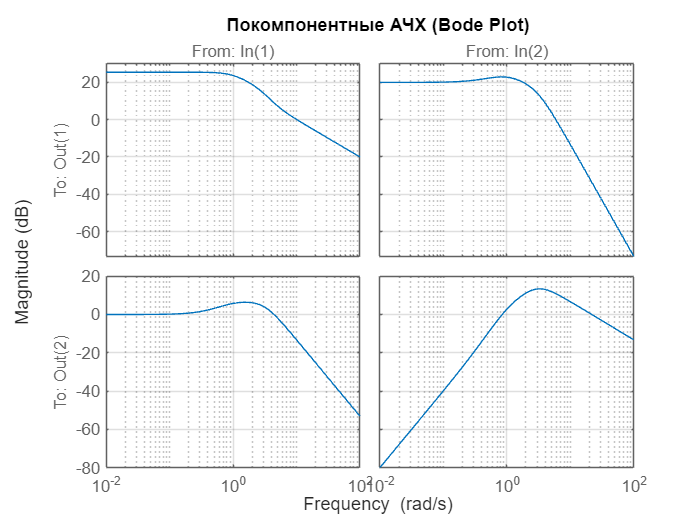

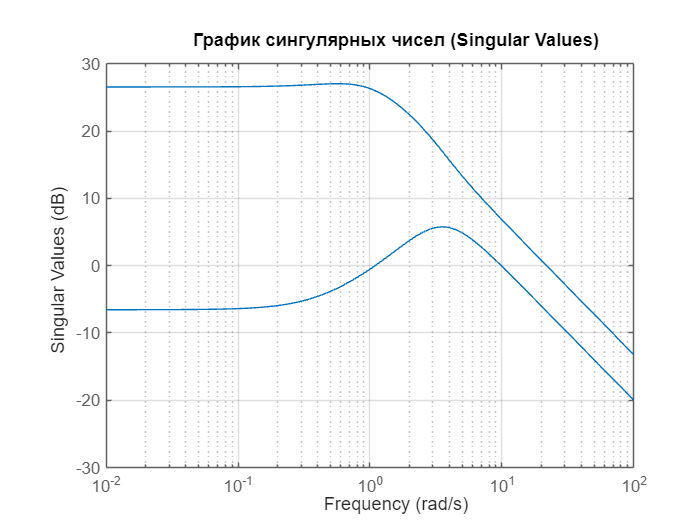

plot_frequency_responses(sys, 8)

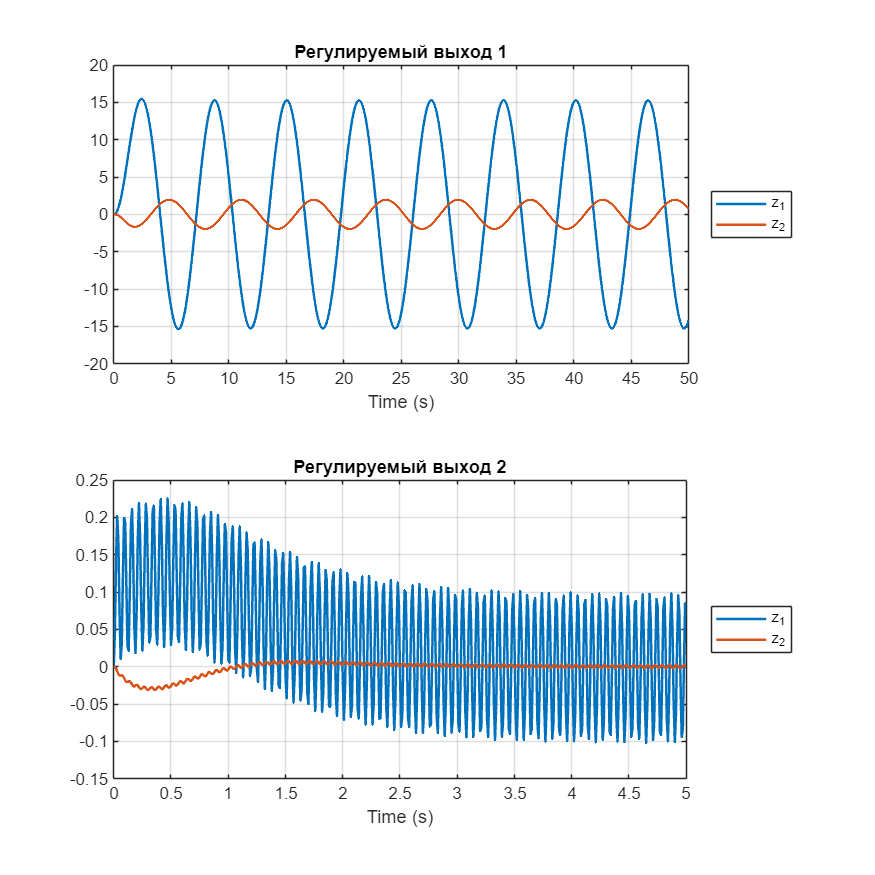

x0 = [0; 0];
x0_hat = [0; 0];

model_name = 'task2';
load_system(model_name);

assignin('base', 'CZ', CZ);
assignin('base', 'DZ', DZ);
assignin('base', 'w', 1);

sim_out = sim(model_name, 'StopTime', num2str(50));
t1 = sim_out.tout;
z1 = squeeze(sim_out.yout{3}.Values.Data);

assignin('base', 'w', 100);
sim_out = sim(model_name, 'StopTime', num2str(5));
t2 = sim_out.tout;
z2 = squeeze(sim_out.yout{3}.Values.Data);

figure('Position', [0 0 700 700]);
m = 2; % Number of rows
n = 1; % Number of columns

subplot(m, n, 1);
plot(t1, z1(1, :), 'LineWidth', 1.5); hold on;
plot(t1, z1(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 1');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

subplot(m, n, 2);
plot(t2, z2(1, :), 'LineWidth', 1.5); hold on;
plot(t2, z2(2, :), '-', 'LineWidth', 1.5);
title('Регулируемый выход 2');
xlabel('Time (s)');
legend({'z_1', 'z_2'}, 'Location', 'eastoutside');
grid on;

% Save the figure
exportgraphics(gcf, ['figs/8_sim.png'], 'Resolution', 500);